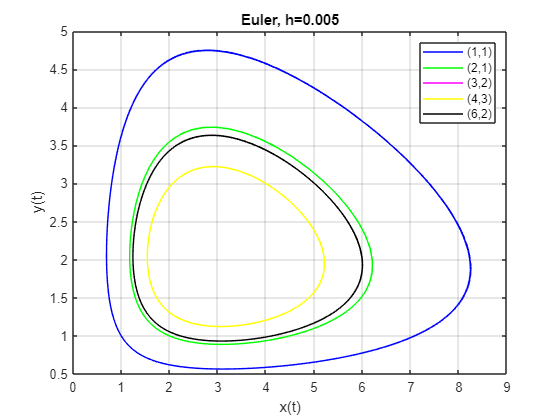

clear all, clc

%===========INPUT================
fx = @(x,y) x*(1-0.5*y);
fy = @(x,y) y*(-0.75+0.25*x);

%Condiciones iniciales 
cond_iniciales = [[1;1] [2;1] [3; 2] [4;3] [6;2]];

inter = [0;30];
H = [0.1];

%===========OUTPUT================
colors = ['b' ; 'g'; 'm' ;'y' ;'k' ;'r'; 'c' ;'b'; 'm'; 'y'; 'k'; 'r'; 'g'; 'c'];
figure
for point=1:length(cond_iniciales)
    for h=1:length(H)
        Z = f_eulerd2(fx,fy,cond_iniciales(:,point),inter,H(h));
        plot(Z(1,1:length(Z)),Z(2,1:length(Z)),colors(point));
        hold on
    end
    grid on
    xlabel('x(t)')
    ylabel('y(t)')
    title('Euler, h=0.005')
    hold on
end
legend('(1,1)','(2,1)','(3,2)','(4,3)','(6,2)')

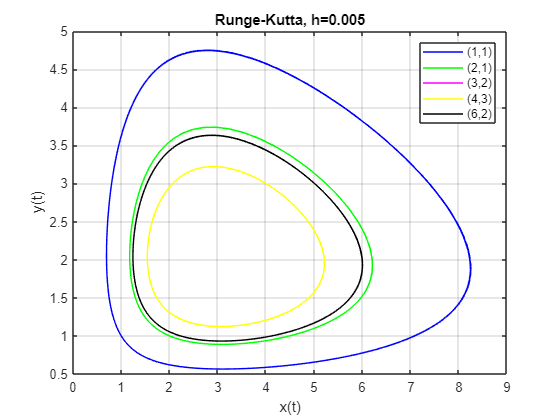

clear all, clc
%===========INPUT================
fx = @(x,y) x*(1-0.5*y);
fy = @(x,y) y*(-0.75+0.25*x);

%Condiciones iniciales 
cond_iniciales = [[1;1] [2;1] [3; 2] [4;3] [6;2]];

inter = [0;30];
H = [0.1];

%===========OUTPUT================
colors = ['b' ; 'g'; 'm' ;'y' ;'k' ;'r'; 'c' ;'b'; 'm'; 'y'; 'k'; 'r'; 'g'; 'c'];
figure
for point=1:length(cond_iniciales)
    for h=1:length(H)
        Z = f_eulerd2(fx,fy,cond_iniciales(:,point),inter,H(h));
        plot(Z(1,1:length(Z)),Z(2,1:length(Z)),colors(point));
        hold on
    end
    grid on
    xlabel('x(t)')
    ylabel('y(t)')
    title('Runge-Kutta, h=0.005')
    hold on
end
legend('(1,1)','(2,1)','(3,2)','(4,3)','(6,2)')